# Image Proccessing Project

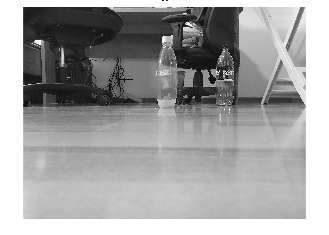

clear,clc,clf;
% galaxy s10- f=26mm
% image 1: D=8cm, x1(soda bottle)=84cm, x2(coke bottle)=115cm
%z=?

%read left image
Il=imread("1l.jpg");
Il=rgb2gray(Il);
Ir=imread("1r.jpg");
Ir=rgb2gray(Ir);

%temp: rotate images
Il=rot90(rot90(Il));
Ir=rot90(rot90(Ir));
%units in cm
%distance between the cameras
D=8;
%focal length
f=2.6;
%get the soda stream bottle
figure();
%imtool(Il);
imshow(Il);
title("Il");

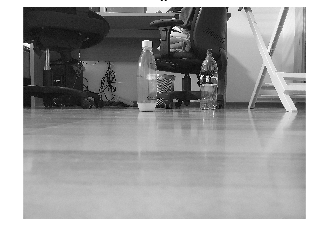

figure();
imshow(Ir);
title("Ir");

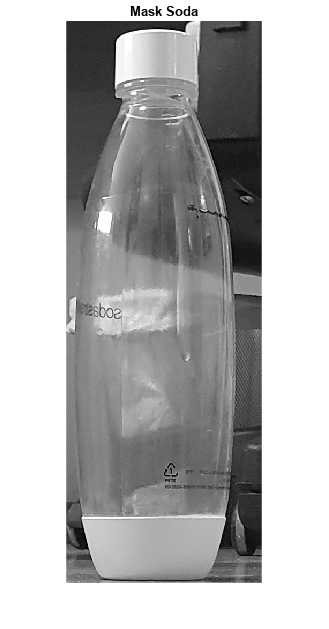


%getting the pixel info of the soda bottle
%(1887, 399)
%(2215, 1447)
mask_soda=Il([399:1447],[1887:2251]);
imshow(mask_soda);
title("Mask Soda");

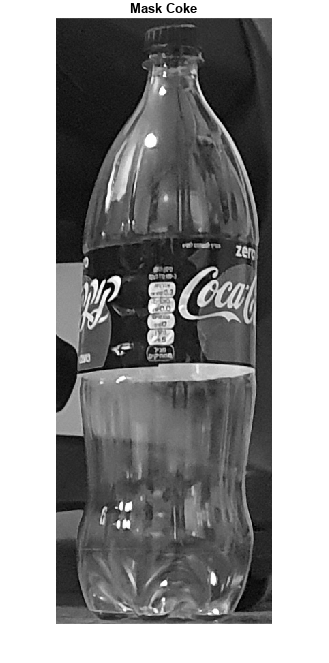

%(2715, 527)
%(3031, 1415)
mask_coke=Il([527:1415],[2715:3031]);
imshow(mask_coke);
title("Mask Coke");

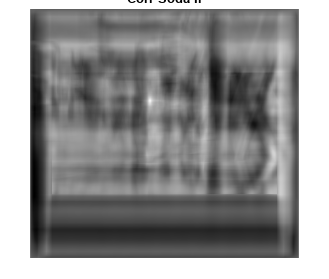


%getting the middle of the masks
x1 = ((1887 + 2251)/2);
y1 = ((399 + 1447)/2);
x2 = ((2715 + 3031)/2);
y2 = ((527 + 1415)/2);

original_point= [y1 x1; y2 x2];

%getting the correlation
% corr_soda1=normxcorr2(mask_soda,Il);
corr_soda2=normxcorr2(mask_soda,Ir);
%corr2_coke1=normxcorr2(mask_coke,Il);
corr2_coke2=normxcorr2(mask_coke,Ir);
% figure();
% imshow(corr_soda1,[]);
% title("Corr Soda lr");
figure();
imshow(corr_soda2,[]);
title("Corr Soda Ir");

%getting the original objects corrdinates
% [original_y1, original_x1] = find(corr_soda1 == max(max(corr_soda1)));
% [original_y2, original_x2] = find(corr_coke1 == max(max(corr_coke1)));
%getting the shifted objects corrdinates
[shifted_y1, shifted_x1] = find(corr_soda2 == max(max(corr_soda2)));
[shifted_y2, shifted_x2] = find(corr2_coke2 == max(max(corr2_coke2)));

%creating a shifted point
shifted_point = [shifted_y1 shifted_x1; shifted_y2 shifted_x2];

%getting the transform using the original point and the shifted point
tform = fitgeotform2d(shifted_point,original_point,"similarity");
%affine output
sameAsInput = affineOutputView(size(Il),tform,"BoundsStyle","SameAsInput");
%fixing the image
imwarp(Il,tform,"OutputView",sameAsInput);


% dispairtyX=original_x1-shifted_x1;
% dispairtyY=original_y1-shifted_y1;
dispairtyX=x1-shifted_x1;
dispairtyY=y1-shifted_y1;

%z=(f*D)/dispairtyX

## chat

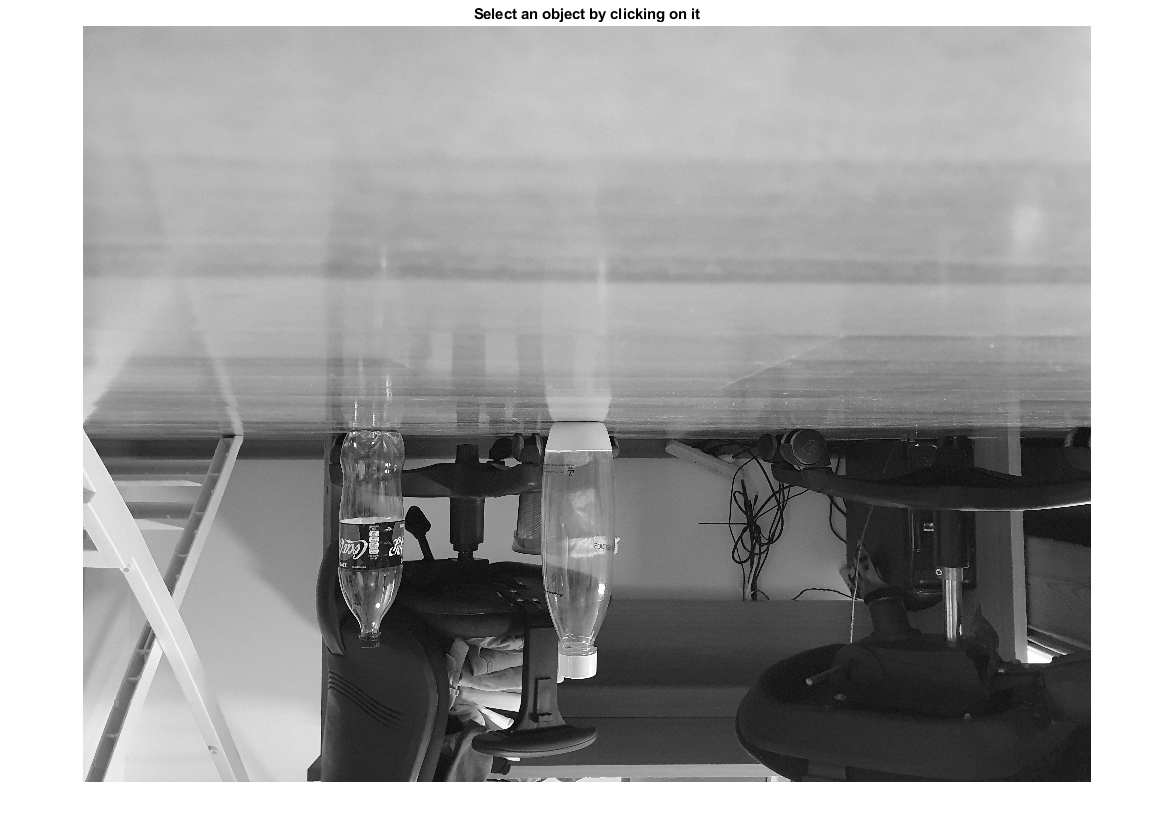

clc,clf,clear;
% Read the two images
image1 = imread('1l.jpg');
image1 = rgb2gray(image1);
image2 = imread('1r.jpg');
image2 = rgb2gray(image2);
% Display the first image
figure;
imshow(image1);
title('Select an object by clicking on it');
object_coords = round(ginput(1)); % Get the coordinates of the selected object


% Get the pixel coordinates of the selected object
object_x = object_coords(1);
object_y = object_coords(2);

% Disparity calculation
window_size = 15; % Size of the matching window
disparity_range = 64; % Range of possible disparities
disparity_map = disparity(image1, image2, 'BlockSize', window_size, 'DisparityRange', [0 disparity_range]);

% Get the disparity value for the selected object
object_disparity = disparity_map(object_y, object_x);

% Calculate the distance (depth) of the object from the camera
D = 8; % Camera displacement (in centimeters)
Z = (2.6 * D) / object_disparity;

% Display the calculated distance
fprintf('The distance of the object is: %.2f centimeters\n', Z);

The distance of the object is: -0.00 centimeters


## chat2

clc,clear,clf;
% Read the two images
image1 = imread('1l.jpg');
image2 = imread('1r.jpg');

% Display the first image
figure;
imshow(image1);
title('Select an object by clicking on it');
object_coords = round(ginput(1)); % Get the coordinates of the selected object

% Get the pixel coordinates of the selected object
object_x = object_coords(1);
object_y = object_coords(2);

% Convert images to grayscale
image1_gray = rgb2gray(image1);
image2_gray = rgb2gray(image2);

% Set stereo parameters
D = 8; % Camera displacement (in centimeters)
F = 1000; % Focal length (in pixels)
window_size = 15; % Size of the matching window

% Extract the matching window from the first image
window1 = image1_gray(object_y - window_size/2 : object_y + window_size/2, ...
                     object_x - window_size/2 : object_x + window_size/2);

% % Initialize variables for best matching disparity and SAD value
% best_disparity = 0;
% best_sad = Inf;
% 
% % Iterate over possible disparities
% for disparity = 0 : 64
%     % Calculate the corresponding column in the second image
%     col2 = object_x - disparity;
%     
%     % Check if the window falls within the second image boundaries
%     if col2 - window_size/2 > 0 && col2 + window_size/2 <= size(image2_gray, 2)
%         % Extract the matching window from the second image
%         window2 = image2_gray(object_y - window_size/2 : object_y + window_size/2, ...
%                              col2 - window_size/2 : col2 + window_size/2);
%         
%         % Calculate the Sum of Absolute Differences (SAD)
%         sad = sum(abs(double(window1(:)) - double(window2(:))));
%         
%         % Update the best disparity if the current SAD is smaller
%         if sad < best_sad
%             best_sad = sad;
%             best_disparity = disparity;
%         end
%     end
% end

% Initialize variables for best matching disparity and SAD value
best_disparity = 0;
best_sad = intmax('int32');

% Iterate over possible disparities
for disparity = 0 : 64
    % Calculate the corresponding column in the second image
    col2 = object_x - disparity;
    
    % Check if the window falls within the second image boundaries
    if col2 - window_size/2 > 0 && col2 + window_size/2 <= size(image2_gray, 2)
        % Extract the matching window from the second image
        window2 = image2_gray(object_y - window_size/2 : object_y + window_size/2, ...
                             col2 - window_size/2 : col2 + window_size/2);
        
        % Calculate the Sum of Absolute Differences (SAD)
        sad = sum(abs(double(window1(:)) - double(window2(:))));
        
        % Update the best disparity if the current SAD is smaller
        if sad < best_sad
            best_sad = sad;
            best_disparity = disparity;
        end
    end
end


% Calculate the distance (depth) of the object from the camera
Z = (2.6 * 8) / best_disparity;

% Display the calculated distance
fprintf('The distance of the object is: %.2f centimeters\n', Z);

## chat3

clear,clc,clf;
% Read the two images
image1 = imread('1l.jpg');
image2 = imread('1r.jpg');


% Display the first image
figure;
imshow(image1);
title('Select an object by clicking on it');
object_coords = round(ginput(1)); % Get the coordinates of the selected object

% Get the pixel coordinates of the selected object
object_x = object_coords(1);
object_y = object_coords(2);

% Convert images to grayscale
image1_gray = rgb2gray(image1);
image2_gray = rgb2gray(image2);

% Set stereo parameters
D = 0.08; % Camera displacement (in meters)
F = 26 * 10^-3; % Focal length (in meters)
baseline = 0.08; % Baseline distance (in meters)

% Set disparity calculation parameters
window_size = 15; % Size of the matching window
max_disparity = 64; % Maximum disparity range

% Set pixel size (estimated for Galaxy S10 rear camera)
pixel_size = 1.26 * 10^-6; % Pixel size in meters

% Extract the matching window from the first image
window1 = image1_gray(object_y - window_size/2 : object_y + window_size/2, ...
                     object_x - window_size/2 : object_x + window_size/2);

% Initialize variables for best matching disparity and SAD value
best_disparity = 0;
best_sad = Inf;

% Iterate over possible disparities
for disparity = 0 : max_disparity
    % Calculate the corresponding column in the second image
    col2 = object_x - disparity;
    
    % Check if the window falls within the second image boundaries
    if col2 - window_size/2 > 0 && col2 + window_size/2 <= size(image2_gray, 2)
        % Extract the matching window from the second image
        window2 = image2_gray(object_y - window_size/2 : object_y + window_size/2, ...
                             col2 - window_size/2 : col2 + window_size/2);
        
        % Calculate the Sum of Absolute Differences (SAD)
        sad = sum(abs(double(window1(:)) - double(window2(:))));
        
        % Update the best disparity if the current SAD is smaller
        if sad < best_sad
            best_sad = sad;
            best_disparity = disparity;
        end
    end
end

% Calculate the distance (depth) of the object from the camera
Z = (F * baseline) / (best_disparity * pixel_size);

% Display the calculated distance
fprintf('The distance of the object is: %.2f centimeters\n', Z * 100);
